# A brief statistical exploration of the Mono Lake data

We can improve our predictive model by adding a measure of uncertainty. We will do this using Monte Carlo methods to simulate the future climate, assuming that the water balance terms vary randomly over time. We will revisit this assumption at the end of the activity.

Before we model our data stochastically using Monte Carlo methods we will perform some exploratory statistics to get a sense of the distributions of our data and the correlations between varialbes.

## Learning Goals

After completing this activity, you should be able to:

- Describe the distribution of a single variable within a data set (univariate analysis) and the correlation between variables (multivariate analysis)

Key MATLAB functions and concepts introduced

- plotmatrix

- corrcoef

- histfit

- normplot

- cov

- mvrnd

## Adding Data

First we'll copy over lines from your initial Mono Lake script that read in the relevant data (pt. 3, except initial value part).

% Read in Vorster measured data using xlsread
% All data are in cells B2:B48, The individal sheets contain the following data:
% 1. Elevation [feet above msl], 2. Volume [Acre-Feet], 3. Area [Acres],
% 4. Gauged stream [flow, Acre-Feet per Year], 5. Diversion [flow, Acre-Feet per Year]
% 6. Ungauged [flow, Acre-Feet per Year], 7. Precipitation [rate, Feet per Year],
% 8. Evaporation [rate, Feet per Year].

% read in data sets that we may use in the model
Q_gauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Gauged stream', 'datarange','B2:B48');
Q_diversion = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Diversion', 'datarange','B2:B48');
Q_ungauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Ungauged', 'datarange','B2:B48');
P_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Precipitation', 'datarange','B2:B48');
E_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Evaporation', 'datarange','B2:B48');

% Read in the Vorster lake survey data for volume conversions
% Columns: 1. Volume (acre-ft), 2. Area (acre), 3. Elevation (ft above msl)
% We'll read in al the numeric values so we can use this simple syntax
Survey = readmatrix('Mono_Lake_Survey.xlsx');

% Read in the historic lake elevation data from the MLC (years in 1st column, elevations in 2nd,
% volume in 3rd, surface area in 4th, all rows 2 to 167. ** Use xlsread to read appropriate
% columns into 3 variables: YR_measured, Z_measured and V_measured. **
YR_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'A2:A167');
Z_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'B2:B167');


## Exploring our data

1. Now we can use some MATLAB tools to explore the statistical properties of the data. The *plotmatrix* command provides a nice tool to visualize the relationships between parameters stored in columns of an array.

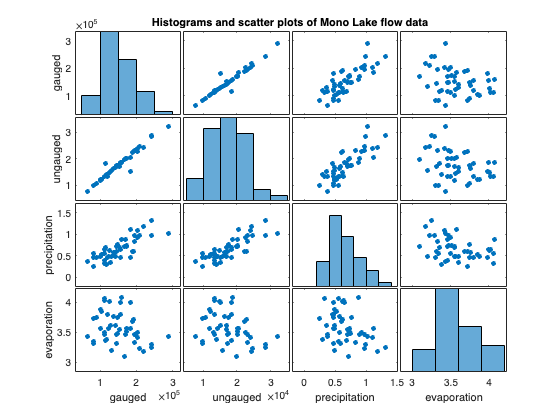

% Group all of the parameter data into a single 47x4 matrix called Q_params
Q_params = [Q_gauged, Q_ungauged, P_rate, E_rate];

% We can visualize the data and correlations using plotmatrix(Q_params)
% We will save the axis handel (ax) so that we can add labels
[~,ax] = plotmatrix(Q_params);

title('Histograms and scatter plots of Mono Lake flow data')

% We'll add some labels to make things clearer
ax(1,1).YLabel.String='gauged';
ax(2,1).YLabel.String='ungauged';
ax(3,1).YLabel.String='precipitation';
ax(4,1).YLabel.String='evaporation';
ax(4,1).XLabel.String='gauged';
ax(4,2).XLabel.String='ungauged';
ax(4,3).XLabel.String='precipitation';
ax(4,4).XLabel.String='evaporation';

The plots along the upper left to lower right diagonal are histograms of each variable (Q_gauged, Q_ungauged, P_rate, E_rate). The other plots are cross plots between each of the two varaibles.

- Which variables are most strongly correlated (appear linear)?

- Which variables are least strongly correlated (appear scattered)?

% corroef calcualtes the correlation coefficient between each of the variables
corrcoef(Q_params)

ans =     1.0000    0.9754    0.8035   -0.3058
    0.9754    1.0000    0.8249   -0.3618
    0.8035    0.8249    1.0000   -0.3710
   -0.3058   -0.3618   -0.3710    1.0000


2. We can use some additional MATLAB tools to inspect the individual varaible to see if they are reasonably described by a normal distribution.

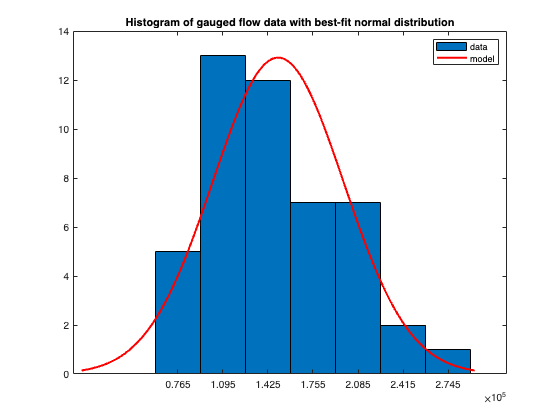

% we can plot histograms with overlying normal distributions using histfit
figure
histfit(Q_gauged)

title('Histogram of gauged flow data with best-fit normal distribution')
legend('data', 'model')

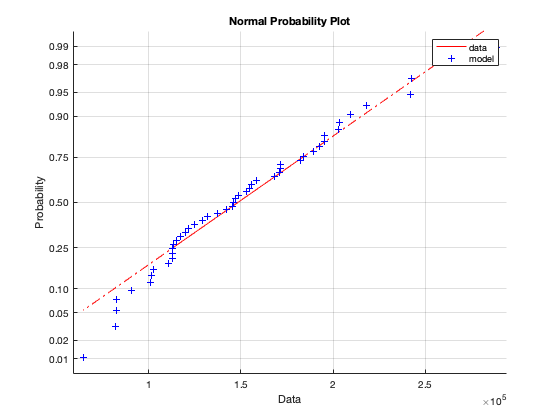


% or visualize the distribution in a probability plot
figure
normplot(Q_gauged)
legend('', 'data', 'model')

Now compare your data to the statistical model (normal distribution).

- How are the data similar to the normal distirbution?

- How are the data different from the normal distirbution?

- What will be the impact on our model if we assume the data are normally distributed?

We will assume normal distirbutions, but should recognize the impact this assumption may have on our models.

For the normal distribution

% The mean provides a measure of central tendency for normally distributed data
Mu = mean(Q_params)

Mu = 1.0e+05 *

    1.4999    0.1748    0.0000    0.0000



% And the covariance matrix (whose diagonal elements are the variance of each
% parameter) provides a measure of the spread about the mean
C = cov(Q_params)

C = 1.0e+09 *

    2.2951    0.2525    0.0000   -0.0000
    0.2525    0.0292    0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000


## Synthesizing random data

In order to simulate our data we want to create synthetic random data sets with the same statistical properties as our original data.

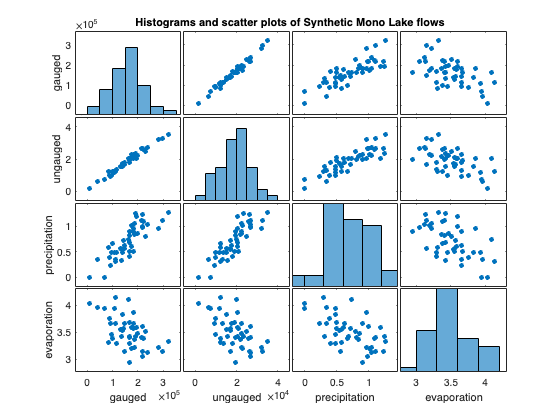

% Use mvrnd(Mu, C, cases) to generate a matrix of 47 random numbers from a multivariate
% normal distribution with the same means and covariance as our data.
r = mvnrnd(Mu,C,45);

% inspect the results to see how they compare to our original data
[~,ax] = plotmatrix(r);

title('Histograms and scatter plots of Synthetic Mono Lake flows')

% Add some labels to make things clearer
ax(1,1).YLabel.String='gauged';
ax(2,1).YLabel.String='ungauged';
ax(3,1).YLabel.String='precipitation';
ax(4,1).YLabel.String='evaporation';
ax(4,1).XLabel.String='gauged';
ax(4,2).XLabel.String='ungauged';
ax(4,3).XLabel.String='precipitation';
ax(4,4).XLabel.String='evaporation';

-  How do the synthetic data above compare to the real data?

Now we are ready to modify our model to estimate a range of future outcomes using our synthetic randomized data.